%~~~~~~~~~~~~~~~~~~~~~~~~~
%
% LookAtFlux91Data_Jim.m
%
% Look at flux 91 data that Jim shared. Will compute gamma etc. similar to
% EQ14 and compare results..
%
% I downloaded the data to my laptop at /Chipod/Flux91/
%
% * I think this data is only for patches?
%
%-------------
% 10/17/16 - A.Pickering - andypicke@gmail.com
%~~~~~~~~~~~~~~~~~~~~~~~~~

clear ; close all

addpath /Users/Andy/Cruises_Research/GenMatlabFunctions/

load('/Users/Andy/Cruises_Research/ChiPod/Flux91/flx91_patch_out_nov94.mat')

% get variables
n2=flx91.bv.^2;% flx91.bv = N?
dtdz=flx91.dtdz;
chi=flx91.chi;
eps=flx91.eps;

% compute gamma from this data
gam =  n2 .* chi ./2 ./ eps ./ (dtdz.^2);



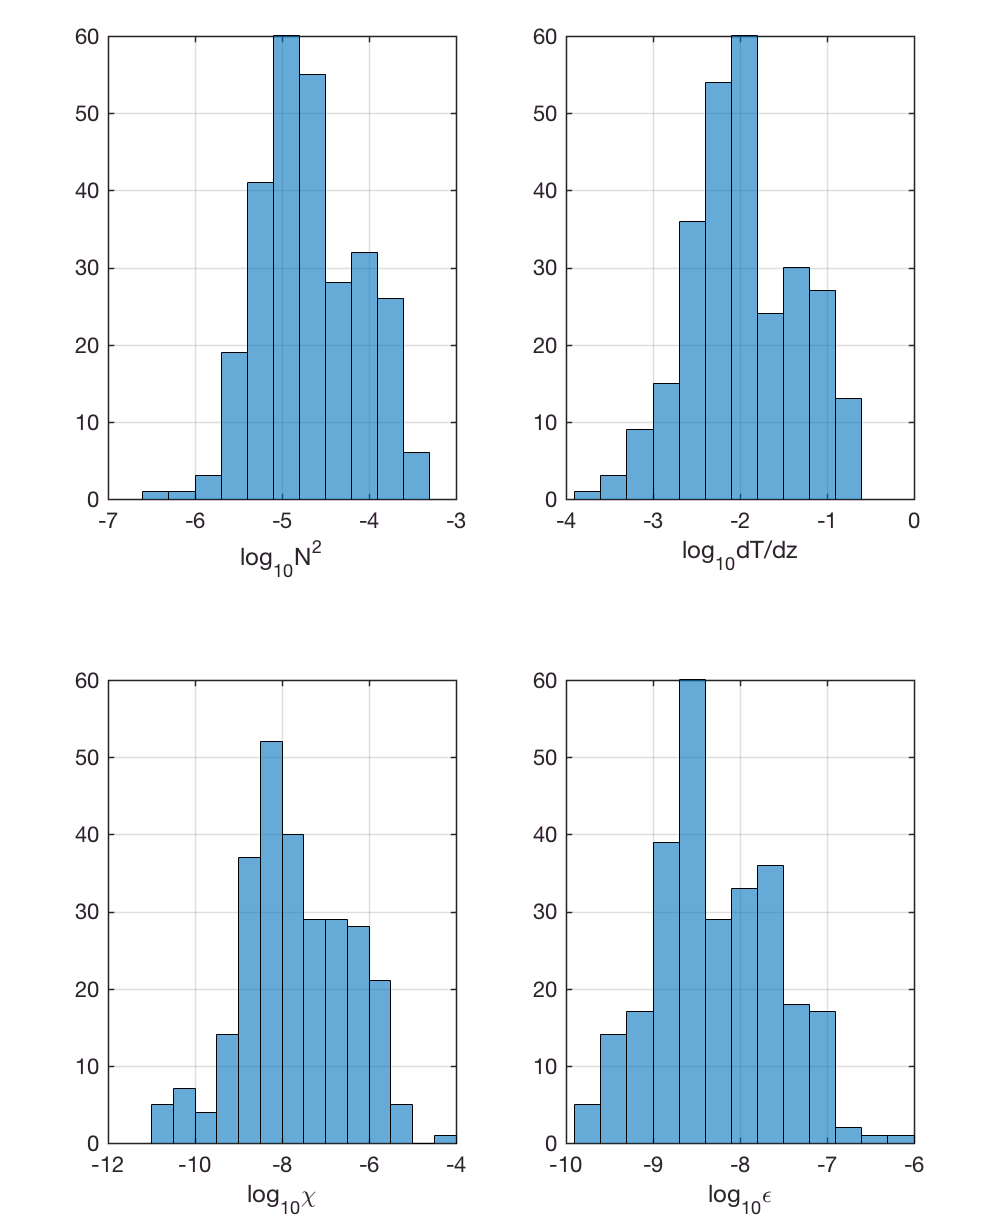

% plot distrbutions of variables
figure(1);clf
agutwocolumn(1)
wysiwyg

subplot(221)
histogram(log10(n2(:)))
xlabel('log_{10}N^2')
grid on

subplot(222)
histogram(real(log10(dtdz(:))))
xlabel('log_{10}dT/dz')
grid on

subplot(223)
histogram(log10(chi(:)))
xlabel('log_{10}\chi')
grid on

subplot(224)
histogram(log10(eps(:)))
xlabel('log_{10}\epsilon')
grid on

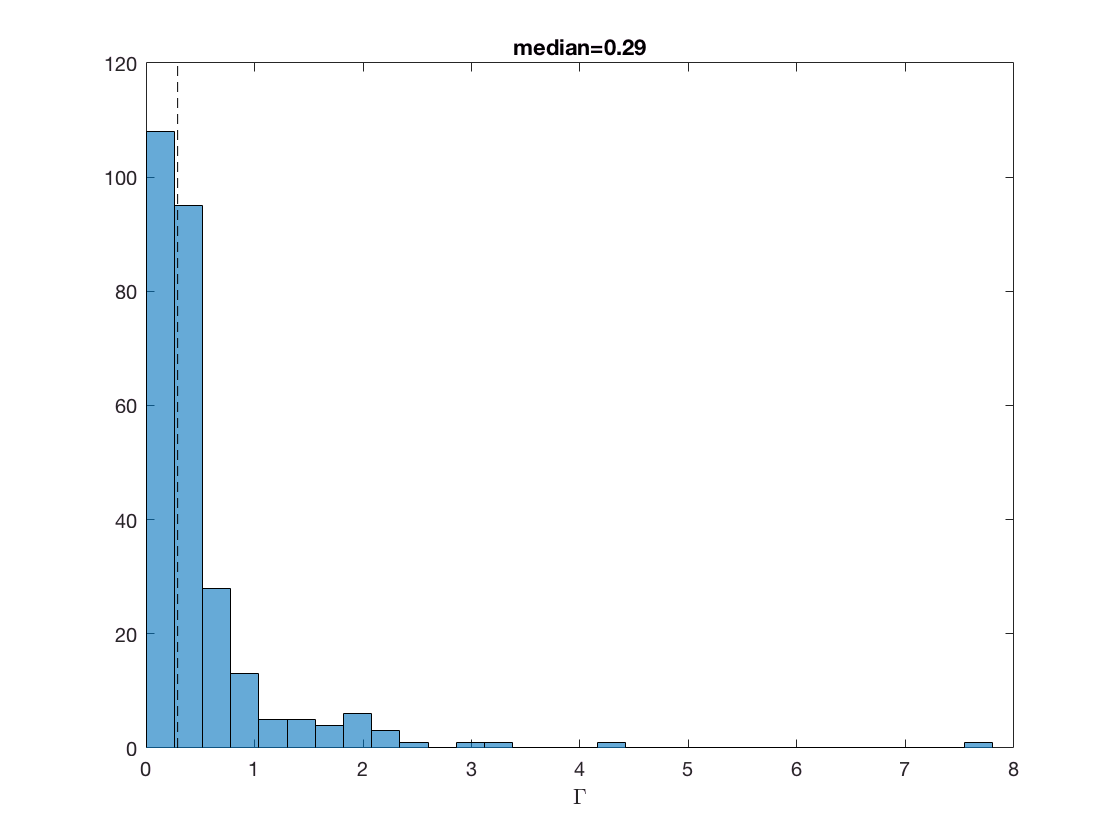

% Plot histogram of gamma computed from these values

figure(1);clf
histogram(gam(:),30);
freqline(nanmedian(gam));
title(['median=' num2str(roundx(nanmedian(gam),2))])
xlabel('\Gamma')

## Scatter Plot of gamma vs each variable

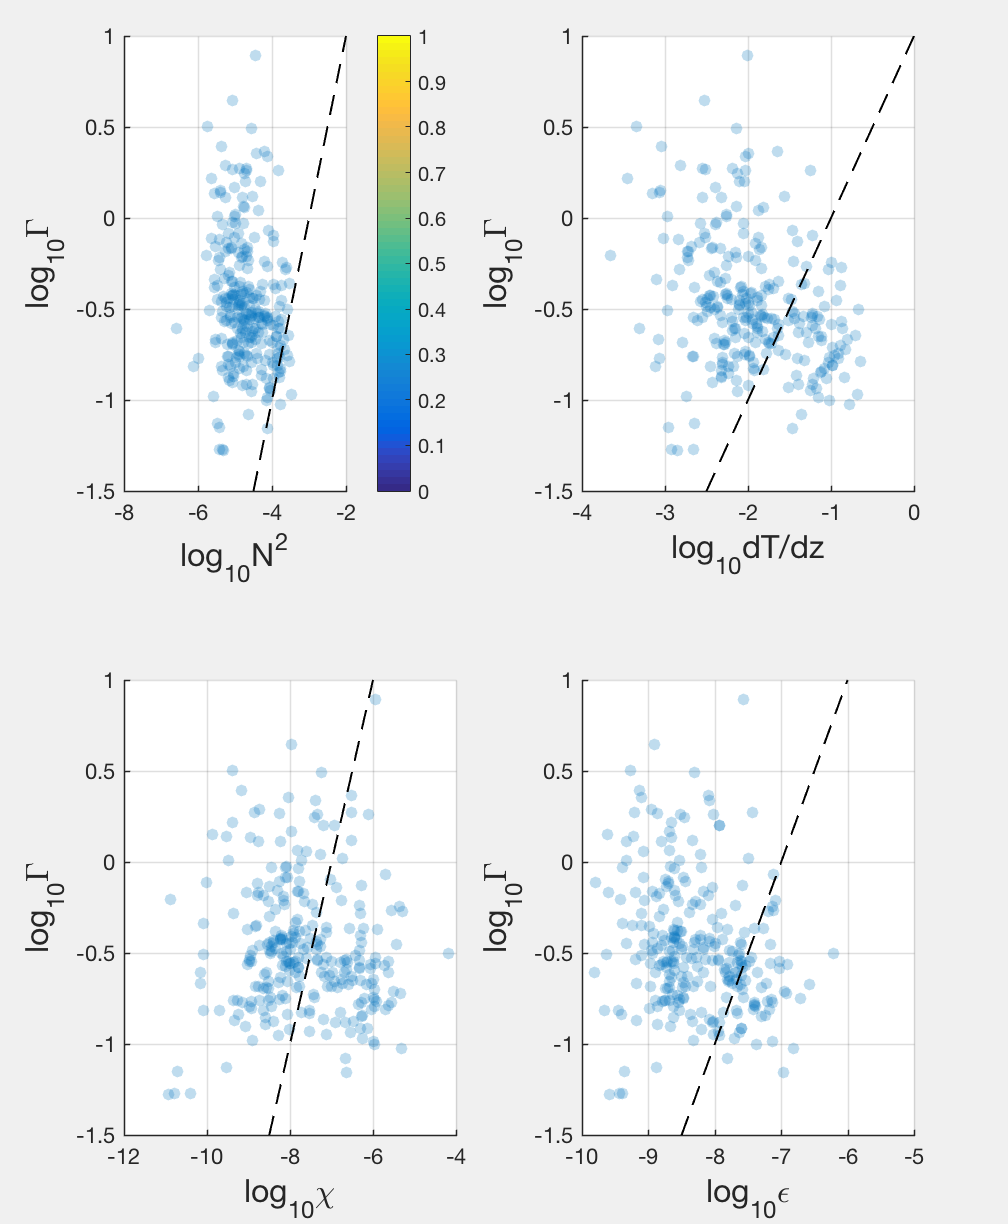

figure(1);clf
agutwocolumn(1)
wysiwyg

%yl=[-6 2];
yl=[-1.5 1];
%yl=[-3 0]

ax1=subplot(221);
%histogram2(real(log10(n2)),log10(gam),200,'DisplayStyle','tile')
scatter(real(log10(n2)),log10(gam),'filled','MarkerFaceAlpha',0.25)
xlabel('log_{10}N^2','fontsize',16)
ylabel('log_{10}\Gamma','fontsize',16)
ylim(yl)
grid on
hold on

xvec=linspace(-6,-2,100);
plot(xvec,xvec+3,'k--')


ax2=subplot(222);
%histogram2(real(log10(dtdz)),log10(gam),200,'DisplayStyle','tile')
scatter(real(log10(dtdz)),log10(gam),'filled','MarkerFaceAlpha',0.25)
xlabel('log_{10}dT/dz','fontsize',16)
ylabel('log_{10}\Gamma','fontsize',16)
ylim(yl)
grid on
hold on
xvec=linspace(-4,0,100);
plot(xvec,xvec+1,'k--')


ax3=subplot(223);
%histogram2(real(log10(chi)),log10(gam),200,'DisplayStyle','tile')
scatter(real(log10(chi)),log10(gam),'filled','MarkerFaceAlpha',0.25)
xlabel('log_{10}\chi','fontsize',16)
ylabel('log_{10}\Gamma','fontsize',16)
ylim(yl)
xlim([-12 -4])
grid on
hold on
xvec=linspace(-12,-4,100);
plot(xvec,xvec+7,'k--')


ax4=subplot(224);
%h=histogram2(real(log10(eps)),log10(gam),200,'DisplayStyle','tile')
scatter(real(log10(eps)),log10(gam),'filled','MarkerFaceAlpha',0.25);
xlabel('log_{10}\epsilon','fontsize',16)
ylabel('log_{10}\Gamma','fontsize',16)
ylim(yl)
grid on
xlim([-10 -5])
hold on
xvec=linspace(-10,-5,100);
plot(xvec,xvec+7,'k--')

linkaxes([ax1 ax2 ax3 ax4],'y')